clear
clc
f_dv=importdata('f_dv_scores.mat');
f_dn=importdata('f_dn_scores.mat');
f_ts=importdata('f_ts_scores.mat');

%distributions of interest
f_dv22=f_dv(:,1);
f_dv12=f_dv(:,4);
f_ts55=f_ts(:,1);
f_ts46=f_ts(:,2);

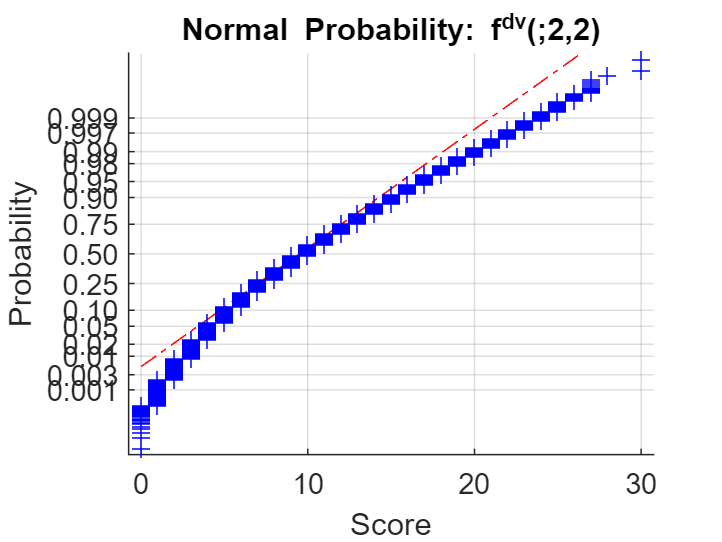

%normality of distributions of interest
figure
normplot(f_dv22)
xlabel('Score')
title('Normal Probability: f^{dv}(;2,2)')

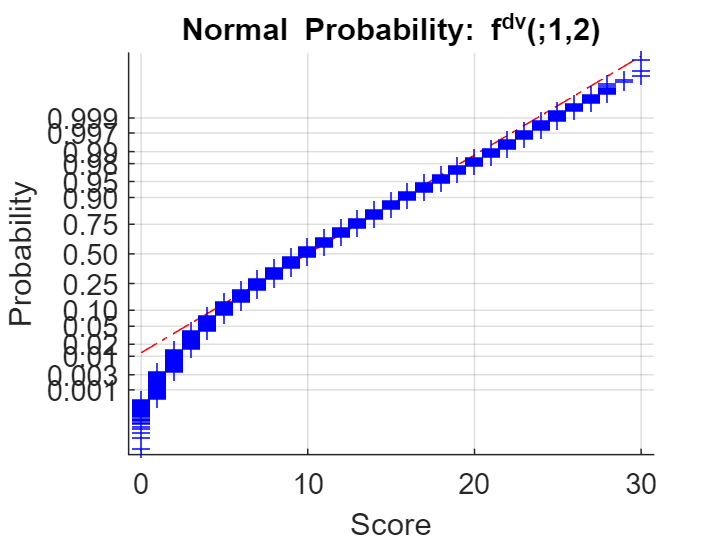


figure
normplot(f_dv12)
xlabel('Score')
title('Normal Probability: f^{dv}(;1,2)')

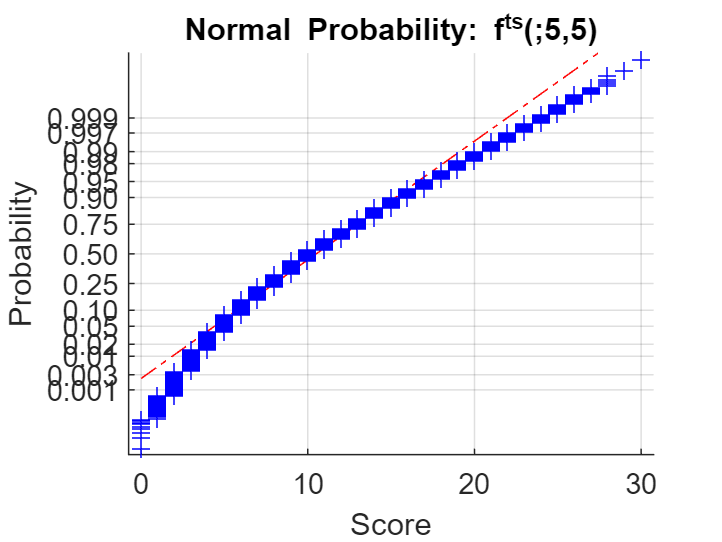


figure
normplot(f_ts55)
xlabel('Score')
title('Normal Probability: f^{ts}(;5,5)')

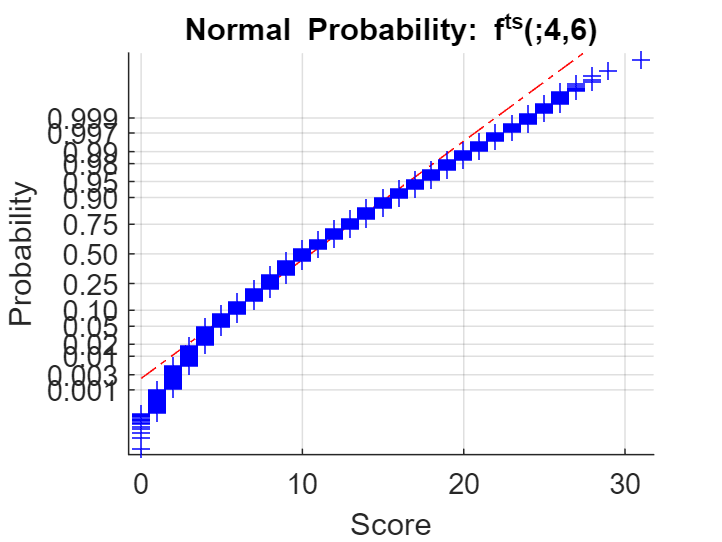


figure
normplot(f_ts46)
xlabel('Score')
title('Normal Probability: f^{ts}(;4,6)')

%comparing means
x=zeros(1,4); s=std(1,4);
x(1)=mean(f_dv22); s(1)=std(f_dv22);
x(2)=mean(f_dv12); s(2)=std(f_dv12);
x(3)=mean(f_ts55); s(3)=std(f_ts55);
x(4)=mean(f_ts46); s(4)=std(f_ts46);
n=length(f_dv22);

Z_0=zeros(4,4);
for i=1:4
    for j=1:4
        if not(i==j)
            %calculate z_0
            Z_0(i,j)=(x(i)-x(j))/(sqrt((s(i)^2+s(j)^2)/n));
        end
    end
end

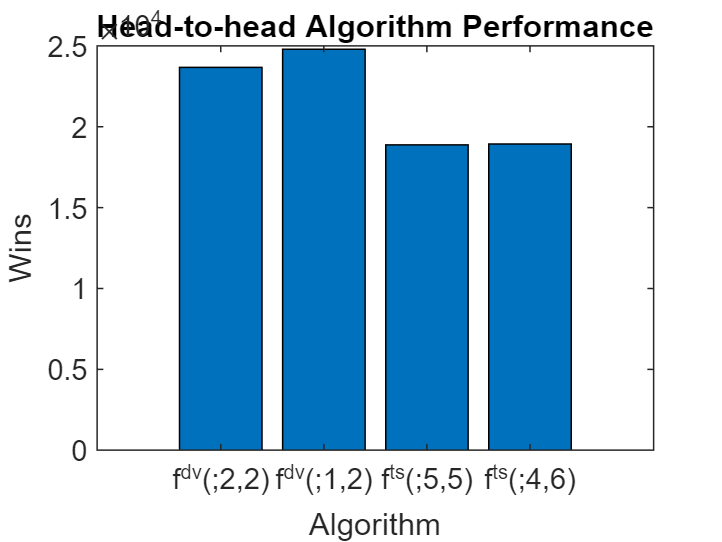

%head to head 4 best
wins=zeros(n,4);

fourbest=[f_dv22,f_dv12,f_ts55,f_ts46];
for i=1:4
    others=1:4; others(i)=[];
    others_scores=fourbest(:,others);
    wins(fourbest(:,i)<min(others_scores,[],2),i)=1;
end
wins=sum(wins);
bar(wins)
alg_names={'f^{dv}(;2,2)','f^{dv}(;1,2)','f^{ts}(;5,5)','f^{ts}(;4,6)',};
ylabel('Wins')
xlabel('Algorithm')
set(gca,'xticklabel',alg_names)
title('Head-to-head Algorithm Performance')

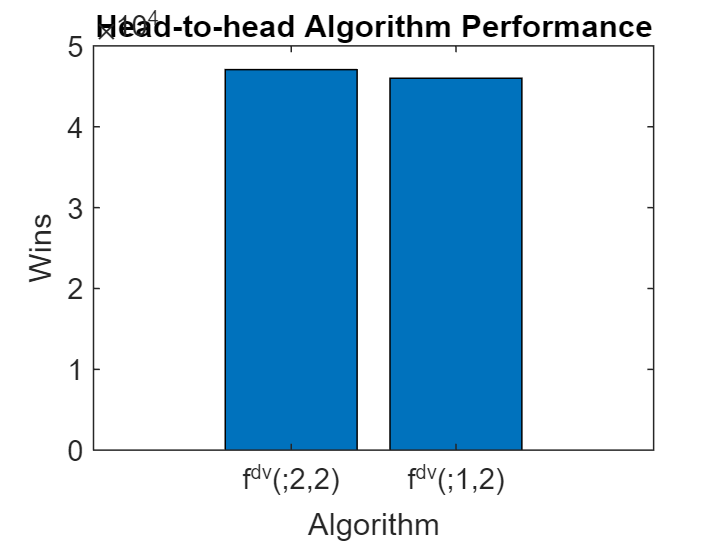


%head to head 2 best
wins=[];
wins(1)=sum(f_dv22<f_dv12);
wins(2)=sum(f_dv22>f_dv12);
bar(wins)
alg_names={'f^{dv}(;2,2)','f^{dv}(;1,2)'};
ylabel('Wins')
xlabel('Algorithm')
set(gca,'xticklabel',alg_names)
title('Head-to-head Algorithm Performance')